# SACE Real-Time Signal-Video Synchronization

## Real-Time Signal-Video Synchronization Tool

This code synchronizes a separately recorded signal and video of a  real-world process, recorded simultaneously but with different start and end times, sampling rates, and time scales. The video is slower and the signal data longer, with the process beginning shortly after recording  starts. The code identifies the process start in both signal and video,  aligning them as a reference point. It adjusts the video to a real-world time scale and trims signal data not included in the video duration.  For visualization, if signal data points outnumber video frames, it  selects the nearest data points; if fewer, it maps one data point to  multiple frames. Users can select specific segments from the video or  signal for synchronization. The output video's frame rate, quality, and  format are customizable.

## Application in SACE Process

This application is designed for signal processing in Spark-Assisted  Chemical Engraving (SACE). It aligns a current signal dataset, recorded  by a current probe and an oscilloscope in CSV format, with a video of the tool tip captured  by a high-speed camera in MP4 format. In operation, the camera starts  recording first, followed by the activation of the SACE machine and  subsequent signal recording by the oscilloscope  within 2-3 seconds. Initially, both data sets show the area around the tool  with no activity, but soon after, the process begins, marked by bubble  formation around the tool in the video and signal fluctuations in the  dataset.

After synchronizing the signal and video data, the application  generates a video that simultaneously displays the current trend and gas film behavior. This feature aids in identifying the correlation between the stages of gas film development and electrical current variations in the SACE process.

## Code Development

### 1- Preparation

In data preparation, it's essential to clearly name the signal dataset and its corresponding video. This step is crucial for aligning and analyzing the data accurately. Additionally, you need to specify several important parameters:

- **Video Frame Rate ('RecordingFrameRate')**: This parameter sets the frame rate of the video, which is vital for synchronizing the video with the signal data.

- **Approximate Process Start Time in the Video ('t_0_Video_')**: This is the estimated time at which the relevant process begins in the video. Identifying this start time allows for locating the corresponding starting frame in the video.

clearvars
% Ensure to input the following data:
FileNameSignal = 'TEK00031.CSV'; 
FileNameVideo = '21_11_23_Letter_C001H001S0002.MP4';
RecordingFrameRate = 38400; % in frames per second (fps)
t_0_Video_ = 68.5;         % in seconds

### 2- Files Reading

In this stage, the program reads signal data from a CSV file, detailing timing, machining current, and voltage, and also assesses the video file's frame rate. It calculates the **'SlowMotionRate'**, a key factor for converting the video to real-world time, essential for accurate data synchronization and analysis.

S = xlsread(FileNameSignal); S(1:find(isnan(S(:,1)), 1, 'last' ),:)=[];
t_ = (S(:,1)-min(S(1,:))); % pure time in second (s)
I_ =  S(:,2);              % pure machining current in amper (A)
E_ =  S(:,3);              % pure machining Voltage in volt (V)

V = VideoReader(FileNameVideo);
VideoFrameRate = V.FrameRate;
SlowMotionRate = RecordingFrameRate/VideoFrameRate;

### 3- Process Beginning

In order to synchronize the signal and video data for subsequent  analysis, it is crucial to identify the exact moments at which the  machining process begins in both data sources. By pinpointing these  reference points, it becomes possible to align the time series data and  accurately identify the corresponding actions in the machining process.  This process of identifying reference points is a critical step in  ensuring the accuracy and reliability of subsequent analyses of the  machining process.

#### 3.1- Signal Pinpointing

To locate the precise moment at which the machining process begins in  the signal data, a plot of the machining current vs. time is generated.  The user must zoom in on the plot to ensure sufficient detail, and then  move the plot to focus on the relevant section. Once the desired point  is identified, the user must press the space button on the keyboard to  activate the cursor. By moving the cursor to the point of interest and  left-clicking, the user can pinpoint the exact moment, **'t_0_Signal'**, at which the  machining process begins.

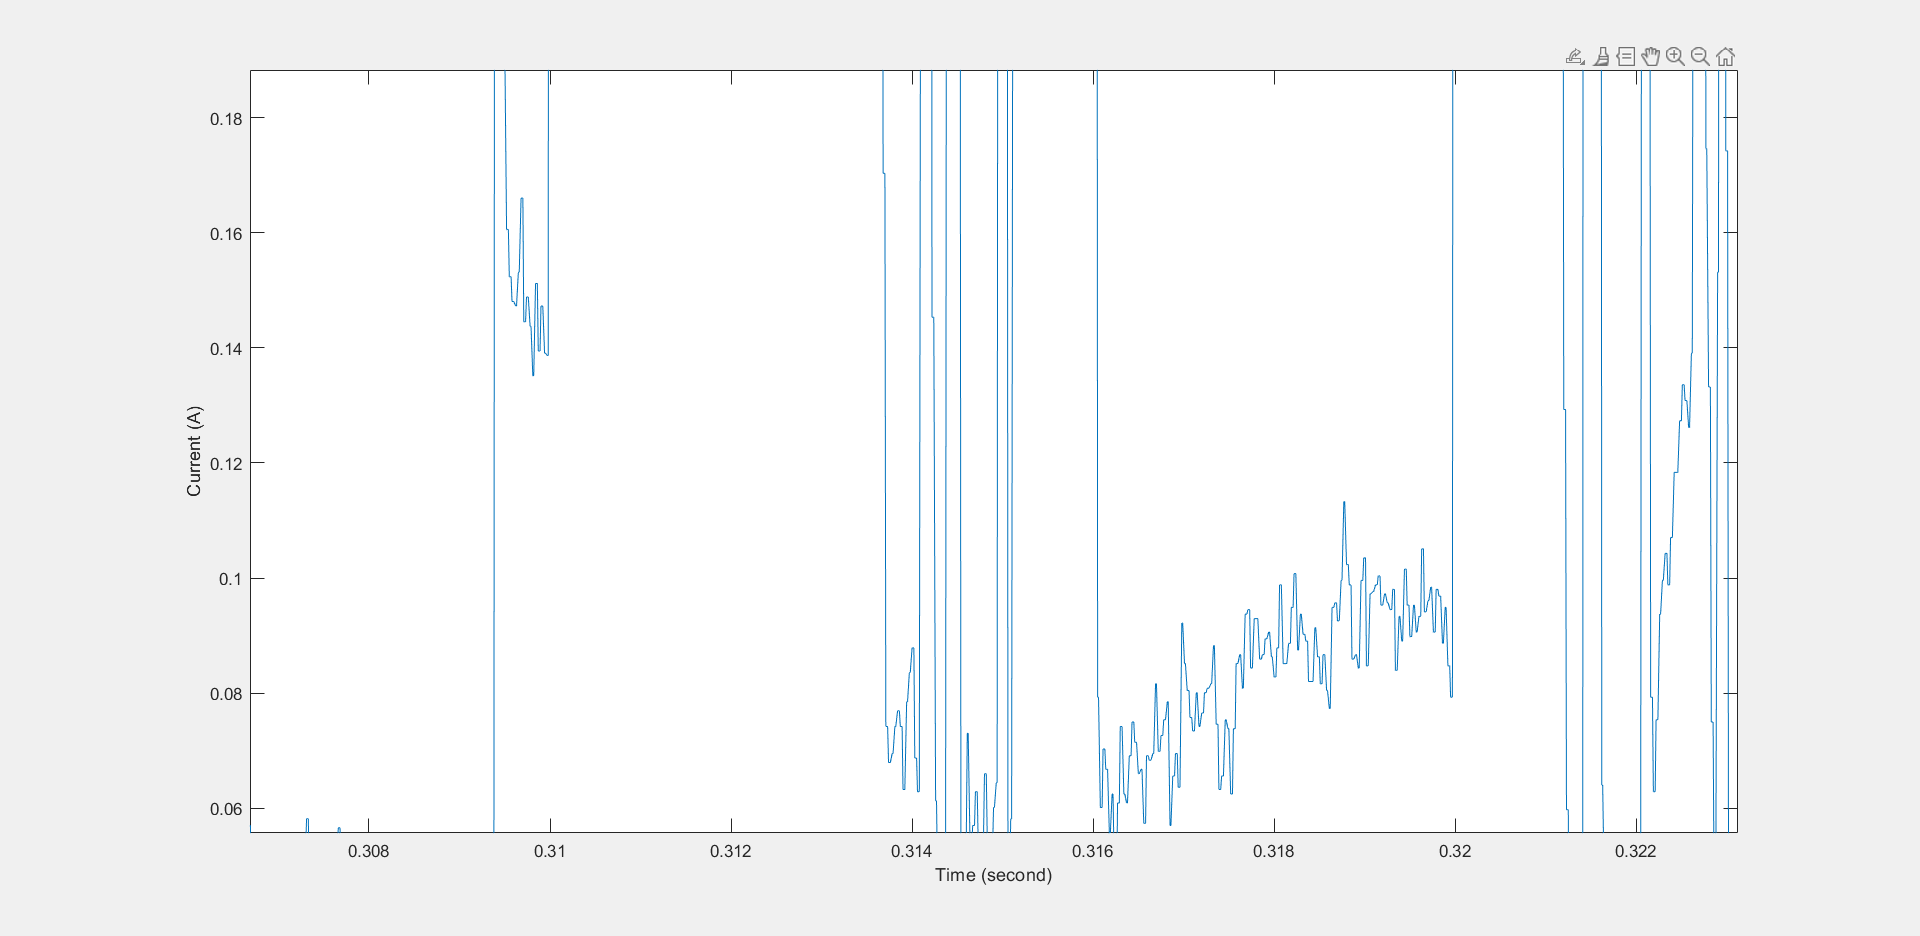

close all
plot(t_,I_); xlabel('Time (second)'); ylabel('Current (A)')
button = 1;   
while button ~= 32
    while waitforbuttonpress && button ~= 32
        [x,y,button] = ginput(1);
    end
end

[~,idx_] = min(abs (t_ - x));
t_0_Signal = t_(idx_)

t_0_Signal = 0.3117

[~,t_0_Signal_idx] = min(abs(t_- t_0_Signal)); % Process begins index

### 3.2- Video Pinpointing

The **'t_0_Video_'** value, which was defined in the preparation stage, is  now used to locate the approximate process beginning time in the video  data. The program displays a frame around this time, allowing the user  to view the relevant section of the video data with greater clarity.

     1



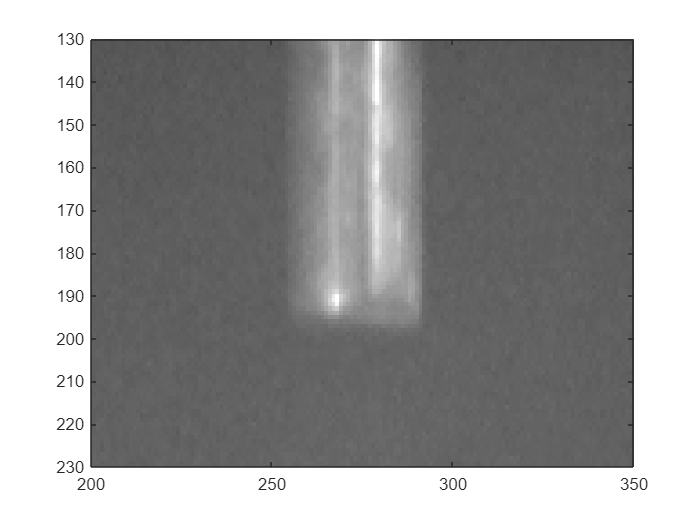

     2



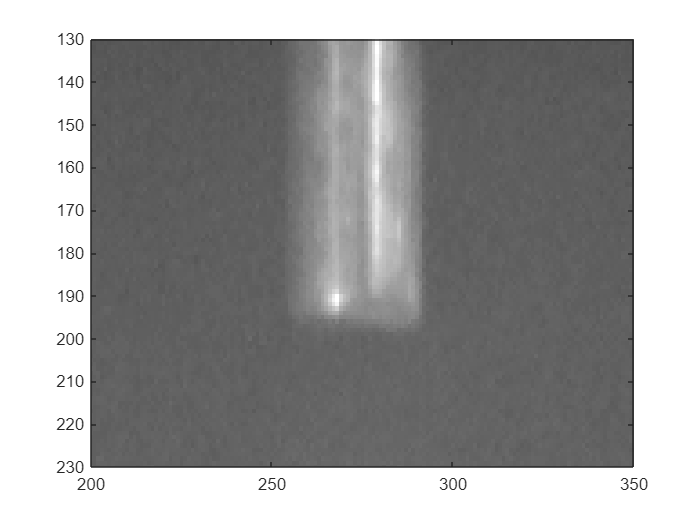

     3



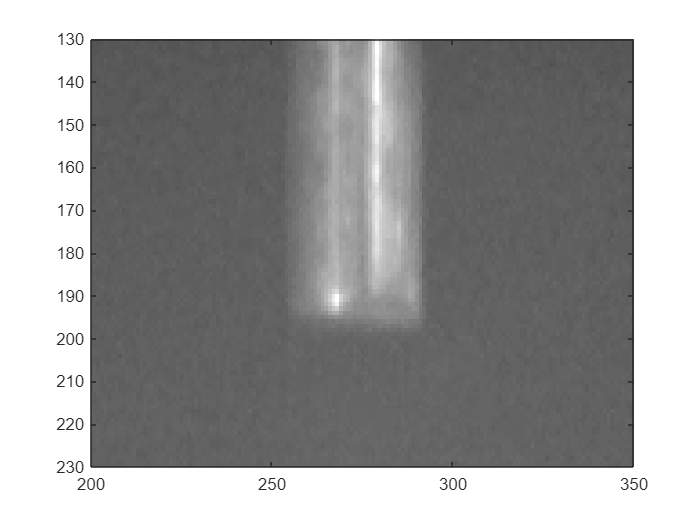

     4



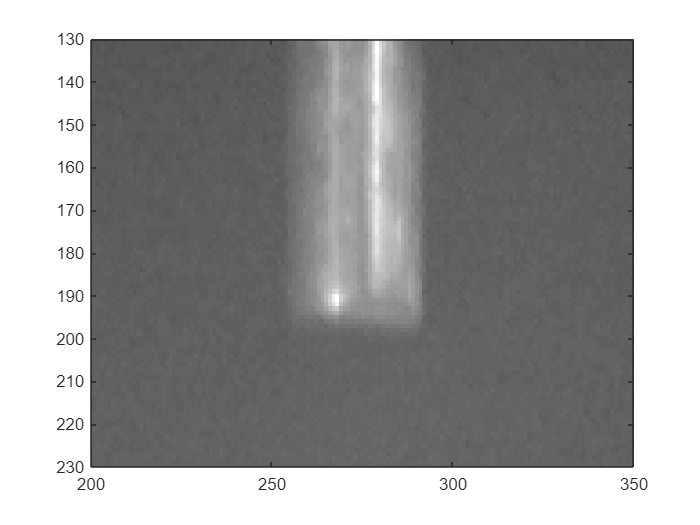

     5



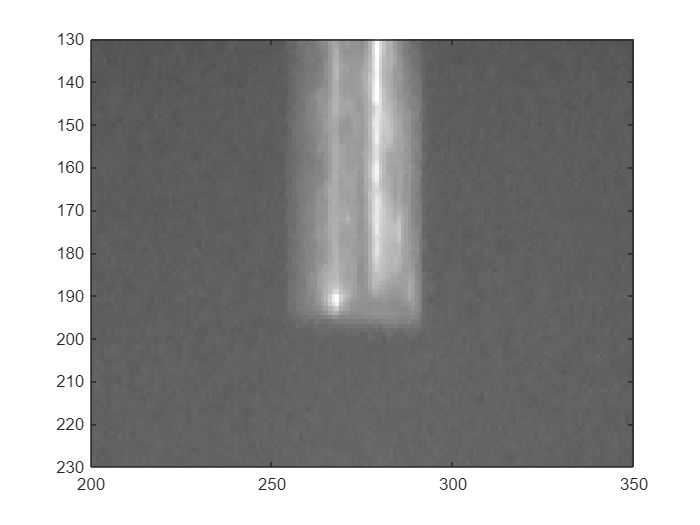

     6



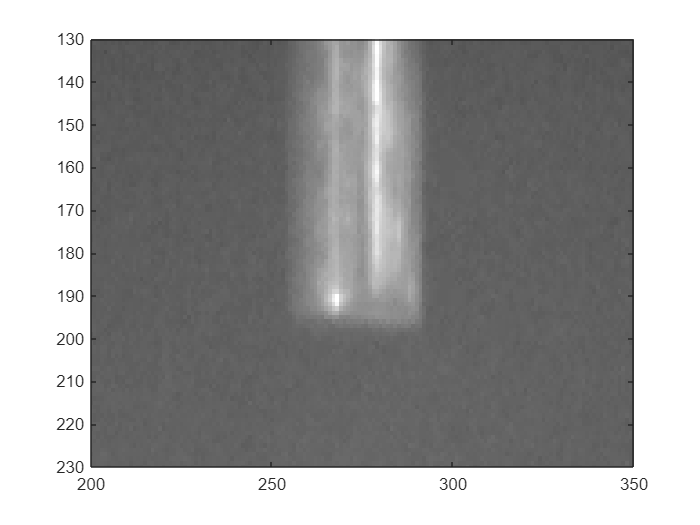

     7



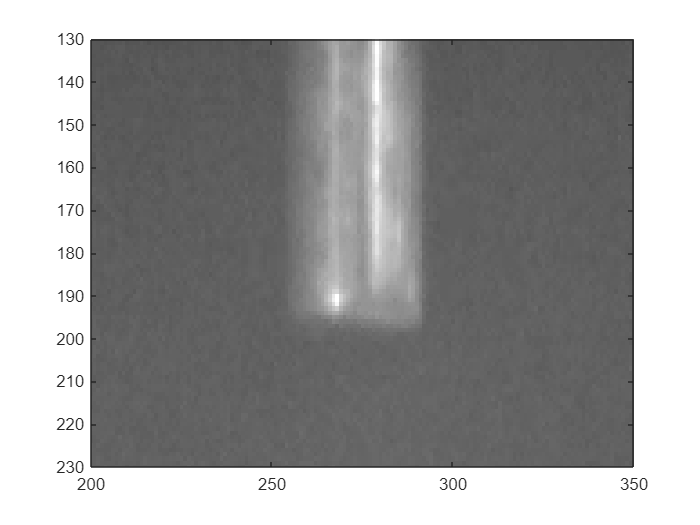

     8



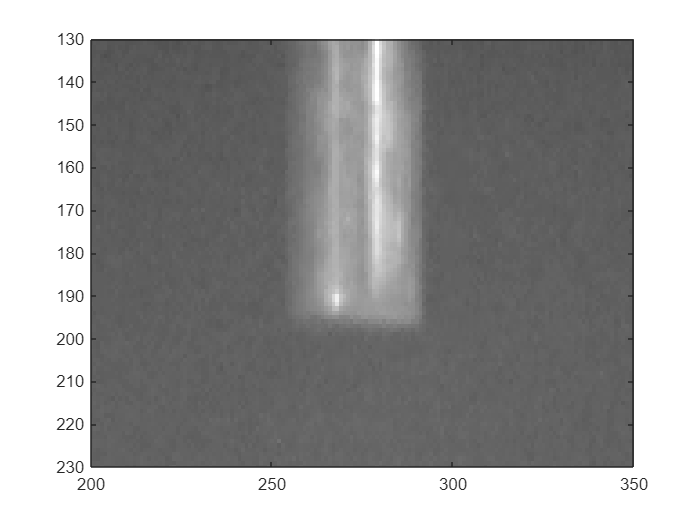

     9



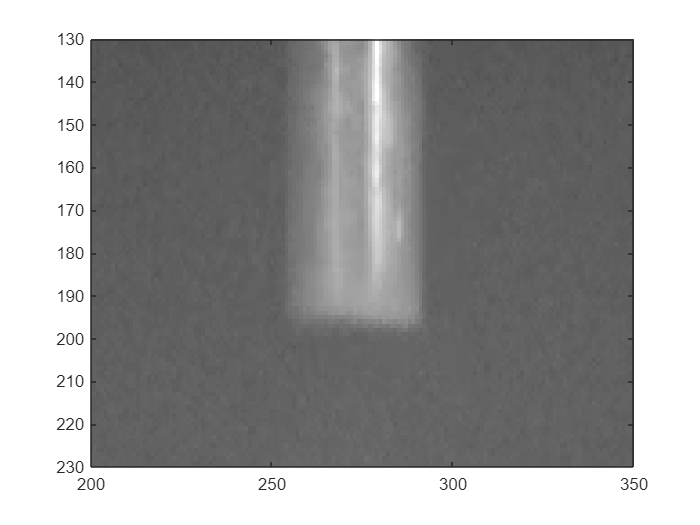

    10



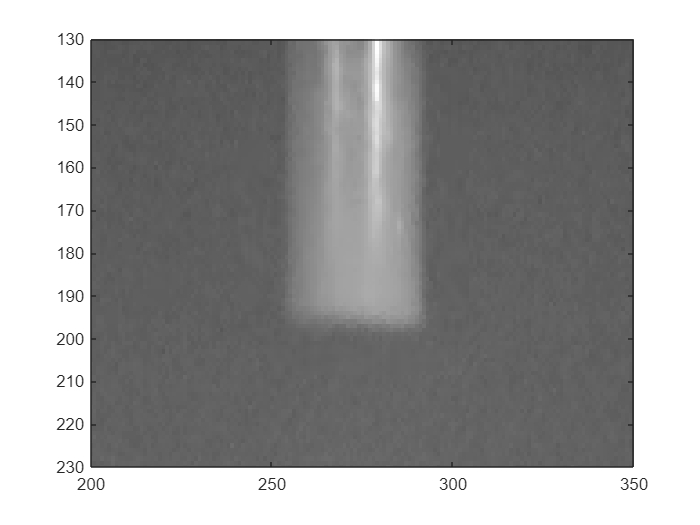

close all
%t_0_Video_ = 138.5; 
V.CurrentTime = t_0_Video_;
NumFrames_ = 10; % Set number of frames to show for locating process start
CurrenTime = zeros(NumFrames_,1);
for i=1:NumFrames_
    disp(i)
    figure(i)
    vidFrame = readFrame(V);
    image(vidFrame);
    CurrenTime(i) = V.CurrentTime;
    xlim([200 350]); ylim([130 230])% Verify this for each video to focus on the tool-tip
end

CurrenTime(end)

ans = 68.8333

The program prompts the user in the command window to specify the exact  process start time, **'t_0_Video'**, based on visual cues from the video. If the initial frames do not align with the process's beginning, the user  can adjust **'t_0_Video_'** by uncommenting line #27 and rerunning section 3.2 to identify the correct frame.

m = input('Which frame is the beginning of theprocess: ');
t_0_Video =  CurrenTime(m-1)

t_0_Video = 68.7333

f_0_idx = round(V.NumFrames*t_0_Video/V.Duration)+1; % Process begins index

### 4- Data Pre-processing

### 4.1- Video time conversion

Recorded video timing is slower, and by using the **'SlowMotionRate'**  obtained in section 2, it can be converted to real-world time, aligning  it with the signal scale to calculate **'t_video'**.

t_video_real = linspace(0,V.Duration,V.NumFrames) - t_0_Video;
t_video_real = t_video_real - t_video_real(f_0_idx);
t_video = t_video_real / SlowMotionRate;

### 4.2- Signal trimming

The recorded signal includes extra sections not covered in the video.  Therefore, it's necessary to trim these additional beginning and ending  parts of the signal for precise alignment with the video. The trimmes data is '**t_signal**'.

t_signal_ = t_ - t_0_Signal;
[~,t_signal_process_s_idx] = min(abs(t_signal_ -t_video(1)));
[~,t_signal_process_e_idx] = min(abs(t_signal_ -t_video(end)));
t_signal = t_signal_(t_signal_process_s_idx:t_signal_process_e_idx);

### 4.3- Signal mapping

The data points in **'t_video'** and** 't_signal'** differ in number. Hence,  **'t_signal'** must be mapped so that each video frame corresponds to a  specific current data point. **'t'**, **'I'**, and **'E'** represent the trimmed and mapped time, machining current, and voltage aligned with the recorded  video's duration. 

idx = round(linspace(t_signal_process_s_idx,t_signal_process_e_idx,V.NumFrames));
t = t_signal_(idx)*1000;
I = I_(idx);
E = E_(idx);
[~,t_0_idx] = min(abs(t-0));

### 5- User Customization

The user can customize the synchronized video's file name, frame rate, quality, and the start and end points of the video. By default, the video starts at the process beginning and ends at the video's conclusion. However, customization is available:

For customization based on the video:    

- Comment out lines #73 and #74,

- Uncomment lines #68 to #70, keeping lines #62 to #65 commented.

For customization based on the signal:

- Uncomment lines #62 to #65,

- Comment out lines #68 to #77.

% Ensure to input the following data:
FileNameVideo_sync = 'Rec_Sync_031.MP4';
FrameRateVideo_sync = V.FrameRate/2;
QualityVideo_Sync = 100;
AnimationOffset = 0.5; % in milliseconds

% Based on signal
% Signal_s = 0.5;
% Signal_e = 0.51;
% [~,frame_s] = min(abs((t/1000)-(Signal_s - t_0_Signal - (AnimationOffset/1000))));
% [~,frame_e] = min(abs((t/1000)-(Signal_e - t_0_Signal )));

% Based on video
% Video_s = 100;
% Video_e = 120;
%Video_0 = Video_s - (AnimationOffset*0.001*SlowMotionRate);

% default
Video_s = t_0_Video;
Video_e = V.Duration;

frame_s = round(V.NumFrames*Video_0/V.Duration)+1;
frame_e = round(V.NumFrames*Video_e/V.Duration)+1;

## 5- Video Annimation

The synchronized video is now set up and ready for animation.

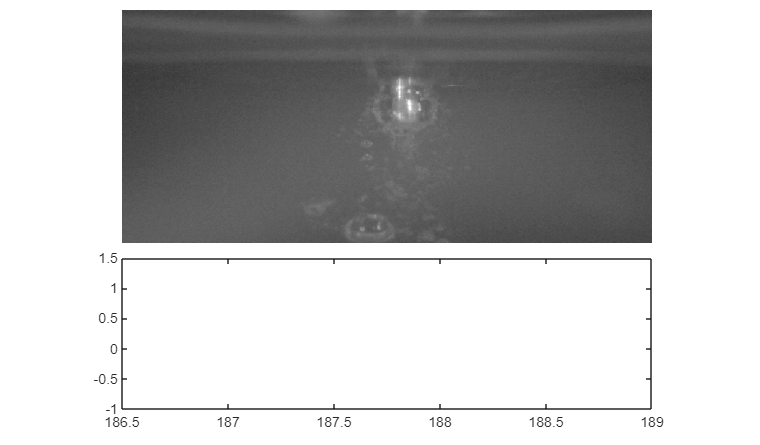

close all
g = figure;
set(g, 'Position', [50 50 1024 600]);

v_ = VideoWriter(FileNameVideo_sync,'MPEG-4');
v_.FrameRate = FrameRateVideo_sync; % Set the frame rate
v_.Quality = QualityVideo_Sync;
open(v_);

V.CurrentTime = Video_0;

ax1 = subplot(2,1,1); % For video
ax2 = subplot(2,1,2); % For machining current
pos_1 = get(subplot(2,1,1),'position');
set(gca, 'Position', [pos_1(1)+0.03,pos_1(2)-0.13,0.9*pos_1(3),0.9*pos_1(3)*768/1024]);
pos_2 = get(subplot(2,1,2),'position');
set(gca, 'Position', [pos_2(1)+0.03,pos_2(2)-0.03,0.9*pos_2(3),pos_2(4)]);

vidFrame = readFrame(V);
image(vidFrame, 'Parent', ax1);
ax1.Visible = 'off';

i=frame_s;
h = plot(t(frame_s:i),I(frame_s:i),'LineWidth',1);

        9400

        9600



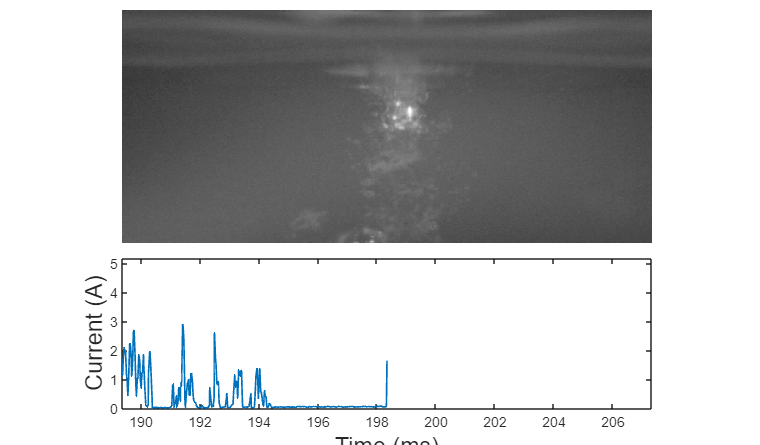


while i<frame_e
    vidFrame = readFrame(V);
    image(vidFrame, 'Parent', ax1);
    ax1.Visible = 'off';

    i=i+1;
    set(h,'YData',I(frame_s:i),'XData',t(frame_s:i))
    ax2.XLim = [t(i)-9 t(i)+9];
    ax2.YLim = [-0.01 max(I)+0.1];
    xlabel('Time (ms)','FontSize',14)
    ylabel('Current (A)','FontSize',14)

    drawnow
    frame = getframe(g);
    writeVideo(v_, frame);

    if rem(i,200) == 0; disp(i);end
end

clear v_ % to be play 